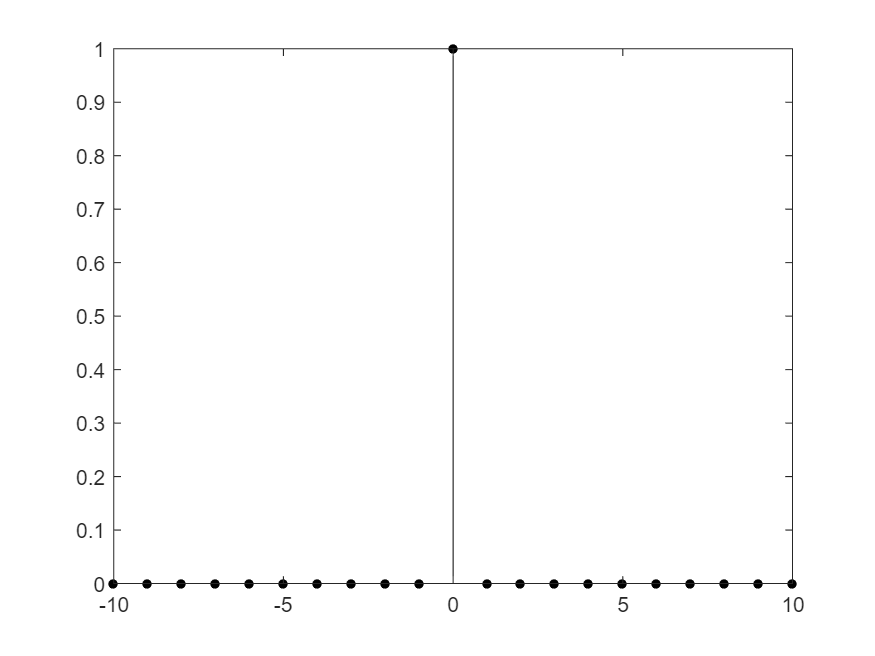

%离散时间系统
%1、单位样本序列
[xn,n]=impseq(0,-10,10);
stem(n,xn,'k','filled','markersize',4);

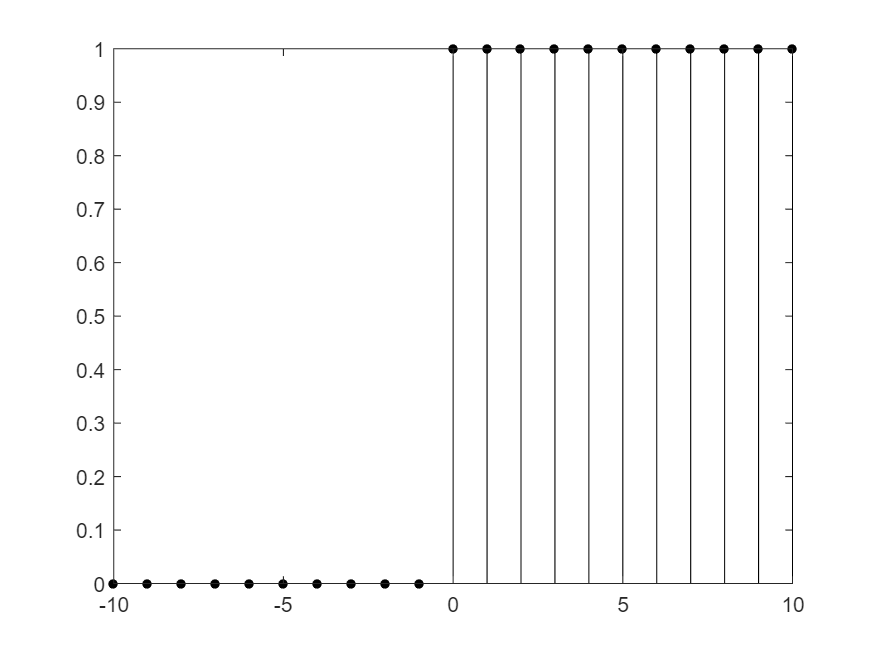

%2、单位阶跃序列
[xn,n]=stepseq(0,-10,10);
stem(n,xn,'k','filled','markersize',4);

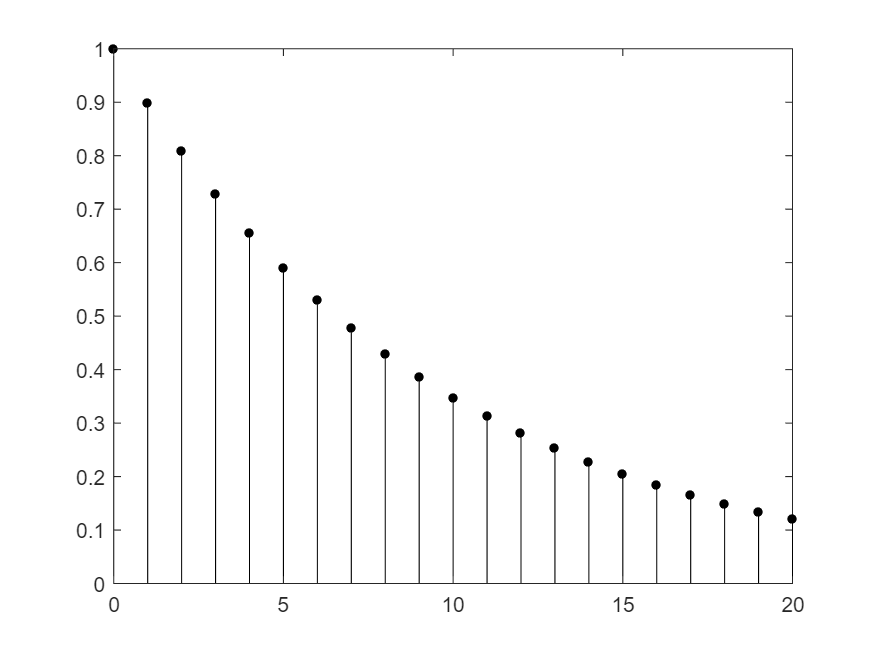

%3、实指数序列
n=0:20;
xn=(0.9).^n;
stem(n,xn,'k','filled','markersize',4);

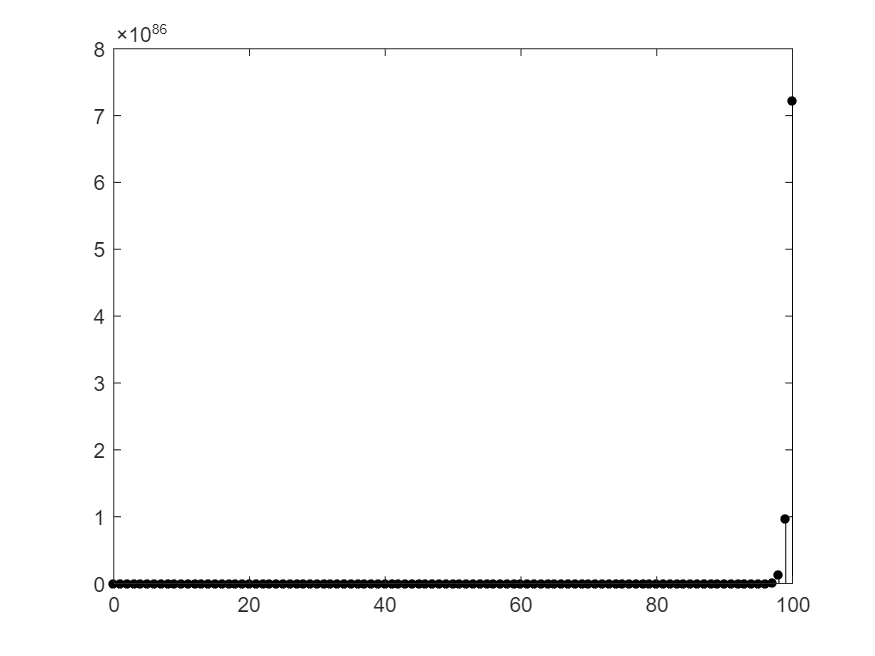

%4、复指数序列
n=[0:100];
x=exp((2+3j)*n);
stem(n,abs(x),'k','filled','markersize',4);

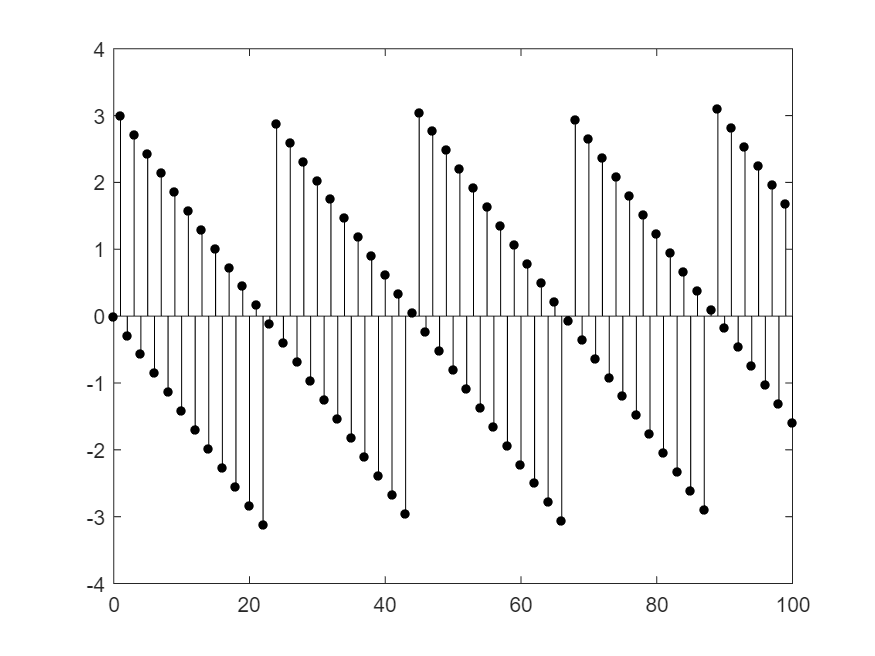

stem(n,angle(x),'k','filled','markersize',4);

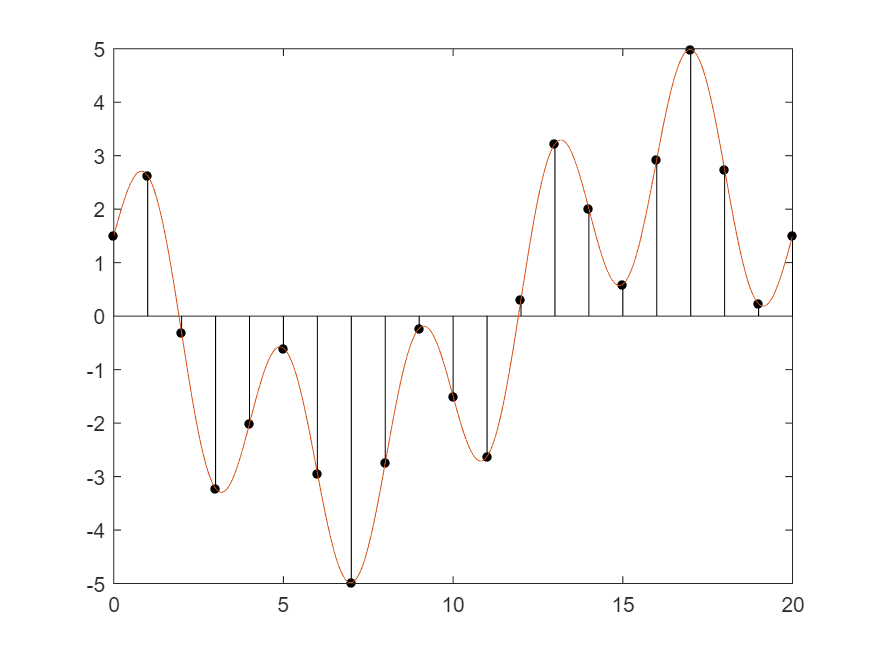

%4、正弦序列
n=0:20;
t=0:0.01:20;
xn=3*cos(0.1*pi*n+pi/3)+2*sin(0.5*pi*n);
stem(n,xn,'k','filled','markersize',4);
hold on
plot(t,3*cos(0.1*pi*t+pi/3)+2*sin(0.5*pi*t))

function [x,n] = impseq(n0,n1,n2)
%Generates x(n) = delta(n-n0);
% n1<n<n2
%----------------------------------------
%[x,n] = impseq(n0,n1,n2)
%
n=(n1:n2);
x=((n-n0)==0);
end

%2、单位阶跃序列
function [x,n] = stepseq(n0,n1,n2)
%Generates x(n) = u(n-n0);
% n1<n<n2
%----------------------------------------
%[x,n] = stepseq(n0,n1,n2);
%
n=n1:n2;
x=((n-n0)>=0);
end


